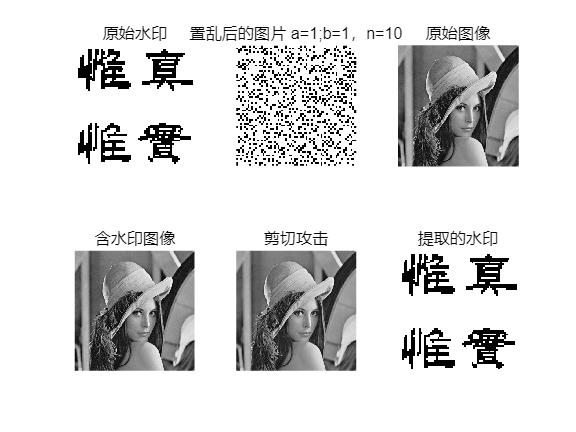

clear;
close all;

E=25; %系数
%读取水印
JJJ = imread('水印(二值).bmp');

%水印置乱
img=imread('水印(二值).bmp');%读取图片，根据Arnold变换的条件，图像必须是正方形
mysize=size(img);%当只有一个输出参数时，返回一个行向量，该行向量的第一个元素时矩阵的行数，第二个元素是矩阵的列数。
if numel(mysize)>2%如果输入是彩色图像
   img=rgb2gray(img); %将彩色到灰度图像的转换
   fprintf("图像为彩色图\n");  %其中\r或者\n表示换行
end
subplot(2,3,1);
imshow(img,[])
title('原始水印');
%img=255*img;
% subplot(2,2,2);
% imhist(img)	%原图的直方图统计

%如果输入的不是正方形图像，则打印如下
[h,w]=size(img);
if h>w
    img = imresize(img, [w w]);
    fprintf("图像长宽不一样，图像可能失真\r");
end
if h<w
    img = imresize(img, [h h]);  
    fprintf("图像长宽不一样,图像可能失真");
end
[h,w]=size(img);

%置乱与逆置乱必须采用共同参数的时候,就相当于密码，才能解密，让图像复原
n=10;%迭代次数
a=1;b=1;
N=h;%N代表图像宽高，宽高要一样

%置乱操作
imgnnn=zeros(h,w);
for i=1:n
    for y=1:h
        for x=1:w           
            xx=mod((x-1)+b*(y-1),N)+1;   %mod取余操作，(a,b)就是a除以b的余数
            yy=mod(a*(x-1)+(a*b+1)*(y-1),N)+1;        
            imgnnn(yy,xx)=img(y,x);                
        end
    end
    img=imgnnn;
end
imgnnn = uint8(imgnnn);

subplot(2,3,2);
imshow(img,[])%置乱后的图片
title('置乱后的图片 a=1;b=1，n=10');

% imwrite (imgnnn,'置乱后的图片.bmp');  %生成图像保存功能


%J=double(imgnnn);
J=double(JJJ);

% 读取原始图像
original_image = imread('lena.jpg'); % 替换为您的图像文件名
I=original_image;
%original_image = rgb2gray(original_image); % 转换为灰度图像

% 将图像分成 8x8 块
block_size = 8;
[rows, cols] = size(original_image);
blocks = mat2cell(original_image, block_size*ones(1, rows/block_size), block_size*ones(1, cols/block_size));

% 对每个块进行 DCT 变换
dct_blocks = cellfun(@(block) dct2(block), blocks, 'UniformOutput', false);

% 提取每个块的 DC 系数
dc_coefficients = cellfun(@(block) block(1, 1), dct_blocks, 'UniformOutput', false);
dc_matrix = cell2mat(reshape(dc_coefficients, rows/block_size, cols/block_size));

% 对 DC 系数矩阵进行 SVD 分解
[U_img, S_img, V_img] = svd(dc_matrix);

% 将水印嵌入到奇异值矩阵 S_img 的对角线元素中
[U, S, V] = svd(J);
new_S_img=S_img + E*S;
% 使用新的奇异值矩阵重构 DC 系数矩阵
new_dc_matrix = U_img * new_S_img * V_img';

% 将新的 DC 系数矩阵重新分配到每个块中
%new_dc_coefficients = mat2cell(new_dc_matrix, 1*ones(1, rows/block_size), 1*ones(1, cols/block_size));
num_blocks = 64; % 获取块的数量
new_dct_blocks = cell(num_blocks, 1); % 初始化新的 DCT 块数组

for i = 1:num_blocks
    for k  = 1:num_blocks
    % 获取当前块
    current_block = dct_blocks{i,k};

    % 替换 DC 系数
    current_block(1, 1) =  new_dc_matrix(i,k);
    
    % 将修改后的块存储到新的数组中
    new_dct_blocks{i,k} = current_block;
    end
end

% new_dct_blocks = cellfun(@(block, dc) block(1,1), dct_blocks, new_dc_coefficients, 'UniformOutput', false);

% 对每个块进行逆 DCT 变换
new_image_blocks = cellfun(@(block) idct2(block), new_dct_blocks, 'UniformOutput', false);

% 重构最终的含水印图像
watermarked_image = cell2mat(new_image_blocks);

watermarked_image = uint8(watermarked_image);
I1=watermarked_image;

% 显示原始图像和含水印的图像
subplot(2, 3, 3);
imshow(original_image,[]);
title('原始图像');

subplot(2, 3, 4);
imshow(watermarked_image, []);
title('含水印图像');

% 保存含水印的图像
%imwrite(watermarked_image, 'watermarked_image.jpg');

%攻击
%高斯滤波攻击
 % H = fspecial('gaussian',3,0.4);
 % watermarked_image = imfilter(watermarked_image,H);
 % 
%G 压缩攻击
quality = 50;
%watermarked_image = imresize(watermarked_image, 0.5); % 缩小图像
imwrite(watermarked_image, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
watermarked_image = imread('temp.jpg'); % 重新读取JPEG图像
%watermarked_image = imresize(watermarked_image, 2); % 放大图像
 
% 剪切攻击
% r = 0.3; % 剪切比例为30%
% sz = size(watermarked_image);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% watermarked_image(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
% % 
% 旋转攻击
% angle = 10; % 旋转角度为20度
% watermarked_image = imrotate(watermarked_image, angle, 'bilinear', 'crop');

%高斯噪声
% mean = 0; % 均值为0
% variance = 0.01; % 方差为0.01
% watermarked_image = imnoise(watermarked_image, 'gaussian', mean, variance);



subplot(2,3,5);imshow(watermarked_image,[]);title('剪切攻击');

%水印提取
blocks_w = mat2cell(watermarked_image, block_size*ones(1, rows/block_size), block_size*ones(1, cols/block_size));
dct_blocks_w = cellfun(@(block) dct2(block), blocks_w, 'UniformOutput', false);
dc_coefficients_w = cellfun(@(block) block(1, 1), dct_blocks_w, 'UniformOutput', false);
dc_matrix_w = cell2mat(reshape(dc_coefficients_w, rows/block_size, cols/block_size));
[U_img_w, S_img_w, V_img_w] = svd(dc_matrix_w);
S1=(S_img_w - S_img)/E;


J1=U *S1* V.';
J1 = imbinarize(J1);
%逆置乱复原
img2=J1;%读取置乱图片
for i=1:n
    for y=1:h
        for x=1:w            
            xx=mod((a*b+1)*(x-1)-b*(y-1),N)+1;%matlab索引中不能是0，要从1开始
            yy=mod(-a*(x-1)+(y-1),N)+1  ;        
            imgnnn(yy,xx)=img2(y,x);                   
        end
    end
    img2=imgnnn;
end
imgnnn = uint8(imgnnn);
% subplot(2,2,4);
% imshow(imgnnn,[])
% title('逆置乱的复原图片');
% imwrite(imgnnn,'逆置乱的复原图片.bmp');%生成图像保存功能
subplot(2, 3, 6);

imshow(J1,[]);
title('提取的水印');


C = normxcorr2(JJJ, J1);
% 提取最大相关系数值
nc_value = max(C(:));
% 输出结果
fprintf('归一化相关性（NC）值为：%.4f\n', nc_value);

归一化相关性（NC）值为：1.0000




psnr_val = psnr(I, I1);
% 输出 PSNR 值
fprintf('PSNR 值为：%.2f dB\n', psnr_val);

PSNR 值为：39.44 dB


psnr_val2 = psnr(I, watermarked_image)

psnr_val2 = 34.2331


[ssim_value, ssim_map] = ssim(I, I1);
% 输出 SSIM 值
fprintf('SSIM 值为：%.4f\n', ssim_value);

SSIM 值为：0.9994




% % 创建表格数据
% data = {
%     'NC', nc_value;
%     'PSNR', psnr_val;
%     'SSIM', ssim_value;
% };
% 
% % 创建表格
% colNames = {'Metric', 'Value'};
% t = uitable('Data', data, 'ColumnName', colNames, 'Position', [20 20 200 150]);


